% clear; close all; clc
% 
% addpath(genpath("images"));
% addpath(genpath("images separadas\prueba_ROI_2"));
% 
% Metadata = readtable("metadata.csv");
% 
% Revisada_B = Metadata.quality==4;
% 
% T = Metadata(Revisada_B,:)
% 
% [N, P] = size(T)

% tick = zeros(length(T.image),1); 
% 
% for i = 1:N
%     file = T.image{i};
%     I = imload(file);
%     if I(146,2611) > 0.9
%         tick(i) = 1;
%     end
% end    
% 
% list = find(tick==0)

file = T.image{5}

file = 'image_0078.jpg'

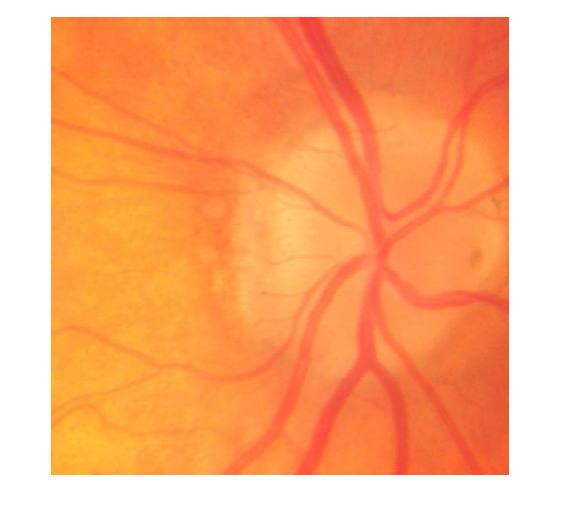

file = {['ROI_' file]};
I = imread(file{1});
I_g = im2double(rgb2gray(I));

figure, imshow(I)

sizes = size(I)

sizes =    801   801     3


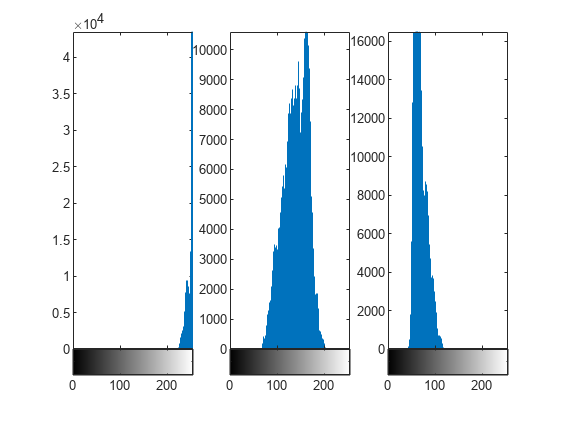

n_pixel = sizes(1)*sizes(2);

I1 = I(:,:,1);
I2 = I(:,:,2);
I3 = I(:,:,3);

figure
subplot(131), imhist(I1)
subplot(132), imhist(I2)
subplot(133), imhist(I3)

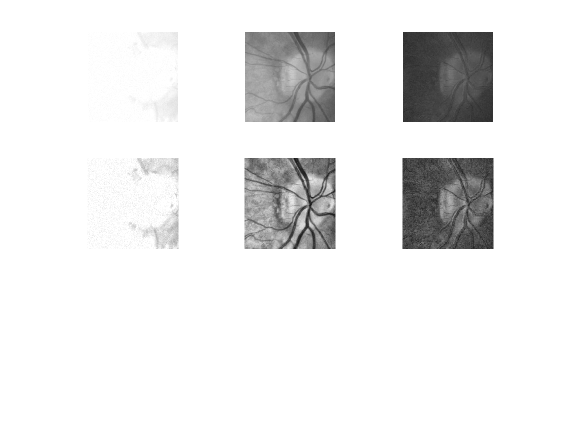


figure
subplot(331), imshow(I1)
subplot(332), imshow(I2)
subplot(333), imshow(I3)
 
I1 = adapthisteq(I1);
I2 = adapthisteq(I2);
I3 = adapthisteq(I3);

subplot(334),imshow(I1)
subplot(335),imshow(I2)
subplot(336),imshow(I3)


m1 = double([max(max(I(:,:,1))) min(min(I(:,:,1))) mean2(I(:,:,1)) std2(I(:,:,1))])

m1 =    255   223   251     6


m2 = double([max(max(I(:,:,2))) min(min(I(:,:,2))) mean2(I(:,:,2)) std2(I(:,:,2))])

m2 =    205    64   140    26


m3 = double([max(max(I(:,:,3))) min(min(I(:,:,3))) mean2(I(:,:,3)) std2(I(:,:,3))])

m3 =    121    39    68    13



m1 = double([max(max(I1)) min(min(I1)) mean2(I1) std2(I1)])

m1 =    255   164   244    16


m2 = double([max(max(I2)) min(min(I2)) mean2(I2) std2(I2)])

m2 =    235    22   142    40


m3 = double([max(max(I3)) min(min(I3)) mean2(I3) std2(I3)])

m3 =    180    31    85    24


Disc segmentation

threshold = [min([0.99 m1(3)*1.1/255]),m2(3)*1.3/255,m3(3)*1.2/255]

threshold =     0.9900    0.7239    0.4000


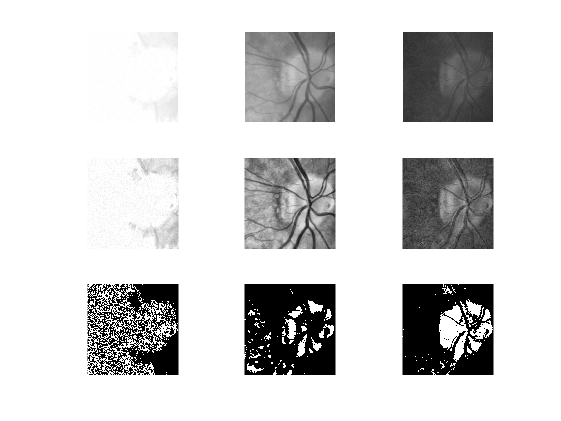


IB1 = imbinarize(I1,threshold(1));
IB2 = imbinarize(I2,threshold(2));
IB3 = imbinarize(I3,threshold(3));

% figure
subplot(337),imshow(IB1)
subplot(338),imshow(IB2)
subplot(339),imshow(IB3)

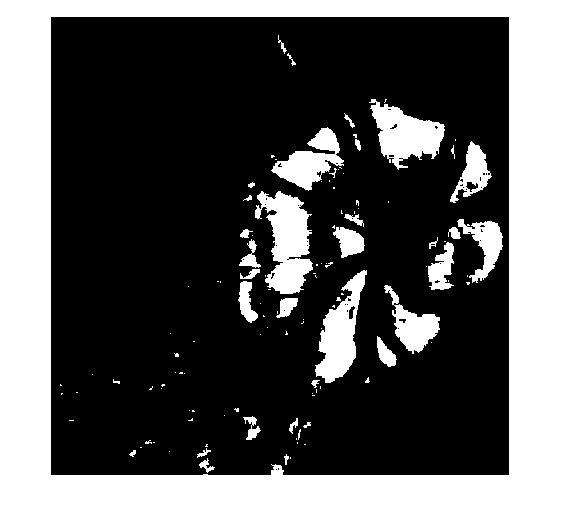


figure, 
imshow(IB2.*IB3)

I4 = ones(sizes(1), sizes(2));

if m1(3)<180 || sum(IB1(:))<n_pixel*0.4
    I4 = I4 .* IB1;
    1
end

ans = 1


if m2(3)>30 && sum(IB2(:))<n_pixel*0.4
    I4 = I4 .* IB2;
    1
end

ans = 1


if m3(3)>30 && sum(IB3(:))<n_pixel*0.4
    I4 = I4 .* IB3;
    1
end

ans = 1

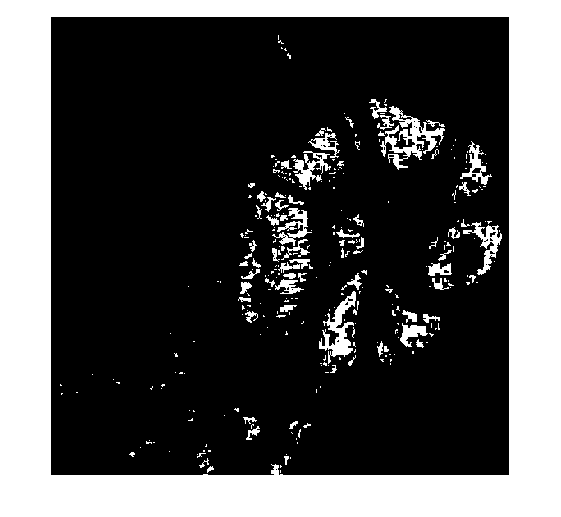


figure
imshow(I4)

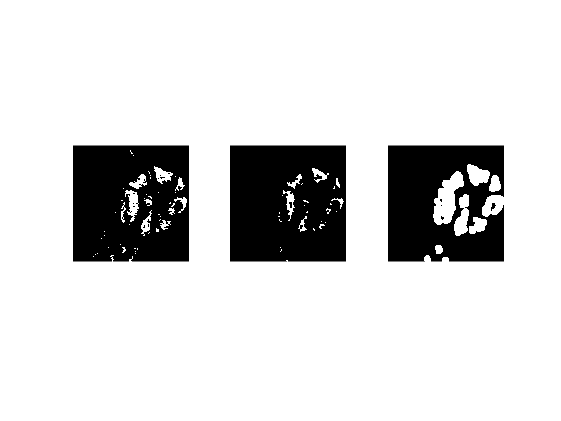

see = strel('disk',20);
see1 = strel('disk',10);
see2 = strel('disk',5);

I4 = imclose(I4,see2);
I5 = imerode(I4,see2);
I6 = imdilate(I5,see);
% I6 = imclose(I6,see1);

figure
subplot(131), imshow(I4)
subplot(132), imshow(I5)
subplot(133), imshow(I6)

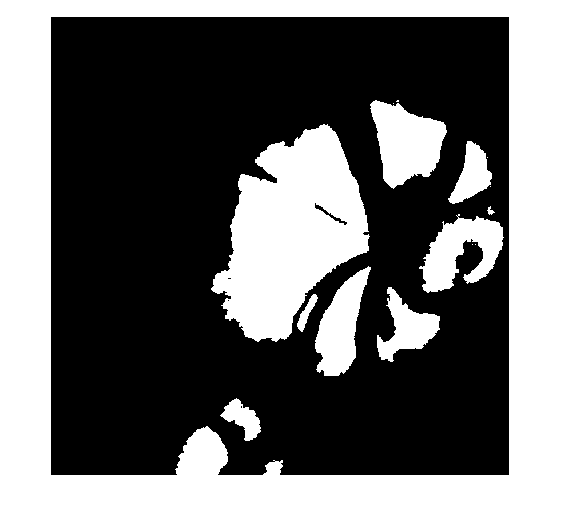


I6 = imbinarize(I6,0);
% figure, imshow(I6)

I7 = activecontour(I_g, I6, 'Chan-vese');
I8 = activecontour(I_g, I6, 'edge');
I9 = I7+I8;
I9 = imbinarize(I9,0);
figure, imshow(I9)

              chan-vese                                    edge                                        both

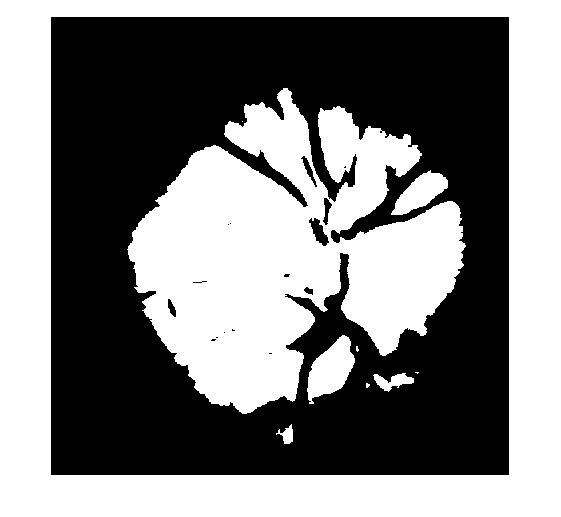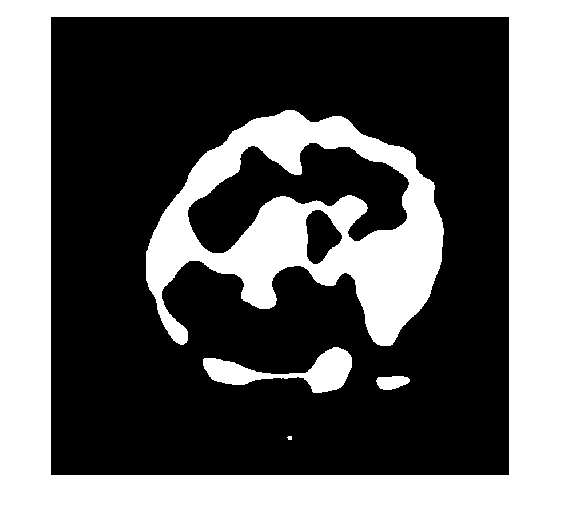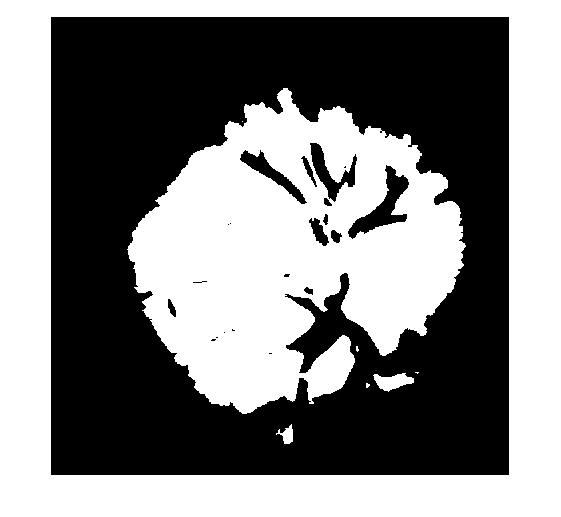

Disc = bwareafilt(I9,[1000 10000000000]);
Disc = imfill(Disc, 'holes');

figure, imshow(Disc)
hold on

[posiciones_y, posiciones_x] = ind2sub(size(Disc), find(Disc==1));
% plot(posiciones_x,posiciones_y,'*')

centro_x1 = round(mean(posiciones_x))

centro_x1 = 493

centro_y1 = round(mean(posiciones_y))

centro_y1 = 409

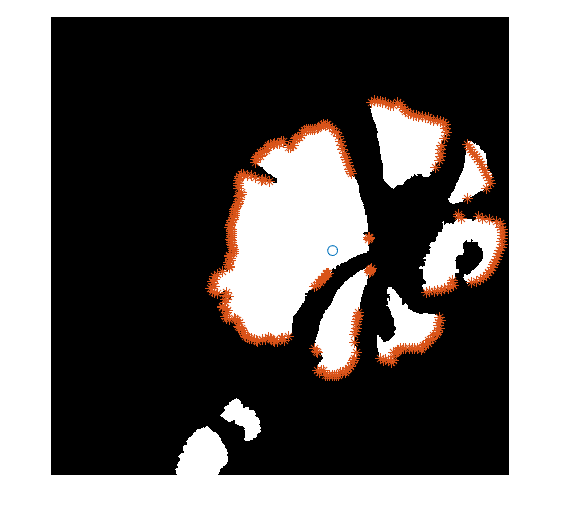

plot(centro_x1,centro_y1,'o')

% Definir el radio máximo
radio_maximo = 300;
% rectangle('Position', [centro_x-radio_maximo, centro_y-radio_maximo, 2*radio_maximo, 2*radio_maximo], 'Curvature', [1, 1], 'EdgeColor', 'r', 'LineWidth', 2);

border = zeros(sizes(1:2));

% Crear un vector de ángulos desde 0 hasta 360 grados
angulos = linspace(0, 2*pi, 360);

% Inicializar un vector para almacenar las coordenadas del último píxel blanco
ultimos_pixeles = zeros(size(angulos));

% Recorrer cada ángulo
for i = 1:length(angulos)
    % Calcular las coordenadas del punto final de la línea
    x_final = round(centro_x1 + radio_maximo * cos(angulos(i)));
    y_final = round(centro_y1 + radio_maximo * sin(angulos(i)));

    % Obtener el perfil de intensidad a lo largo de la línea
    perfil = improfile(Disc, [centro_x1, x_final], [centro_y1, y_final],300);
%     plot([centro_x, x_final], [centro_y, y_final]) %plotear las lineas

    % Encontrar los índices de los píxeles blancos en el perfil
    indices_blancos = find(perfil > 0);

    % Almacenar las coordenadas del último píxel blanco
    ultimo_radio = indices_blancos(end);

    x_border(i) = round(centro_x1 + ultimo_radio * cos(angulos(i)));
    y_border(i) = round(centro_y1 + ultimo_radio * sin(angulos(i)));
    border(y_border(i),x_border(i)) = 1;
end
    plot(x_border,y_border,'*')

figure
imshow(border)
hold on
plot(x_border,y_border,'*') %'-'
centro_x = round(mean(x_border))

centro_x = 509

centro_y = round(mean(y_border))

centro_y = 394

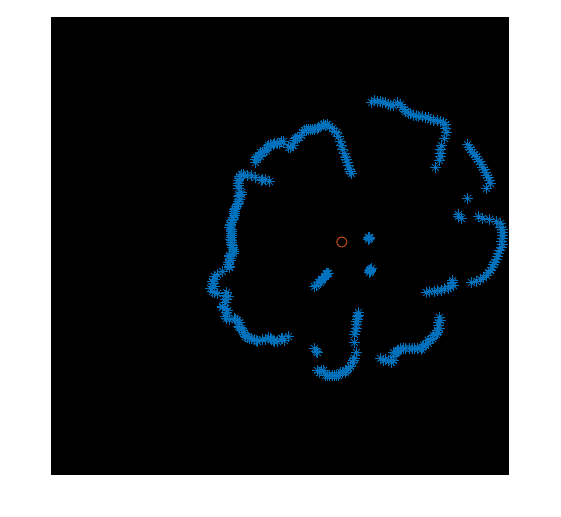

plot(centro_x,centro_y,'o')

% Calcular la distancia euclidiana entre cada píxel del borde y el centroide
distancias = pdist2([x_border', y_border'], [centro_x,centro_y]);
% otra forma de hacerlo     (x - centro_x).^2 + (y - centro_y).^2 


% Calcular la distancia máxima y mínima
[distancia_maxima, I_max] = max(distancias)

distancia_maxima = 282.2145

I_max = 355

[distancia_minima, I_min] = min(distancias)

distancia_minima = 47.1699

I_min = 343

distancia_media = mean(distancias)

distancia_media = 208.8486

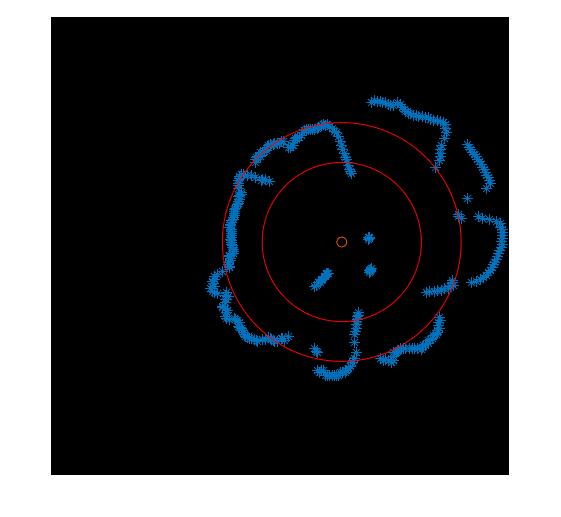


% plot(x_border(I_max),y_border(I_max),'o')
% plot(x_border(I_min),y_border(I_min),'o')

radius = distancia_media;
radius1 = distancia_maxima;
radius2 = distancia_minima;
% radius3 = distancia_minima+(distancia_media-distancia_minima)/2;
radius3 = 2*distancia_media/3;

rectangle('Position', [centro_x-radius, centro_y-radius, 2*radius, 2*radius], 'Curvature', [1, 1], 'EdgeColor', 'r', 'LineWidth', 0.5);
% rectangle('Position', [centro_x-radius1, centro_y-radius1, 2*radius1, 2*radius1], 'Curvature', [1, 1], 'EdgeColor', 'r', 'LineWidth', 0.5);
% rectangle('Position', [centro_x-radius2, centro_y-radius2, 2*radius2, 2*radius2], 'Curvature', [1, 1], 'EdgeColor', 'r', 'LineWidth', 0.5);
rectangle('Position', [centro_x-radius3, centro_y-radius3, 2*radius3, 2*radius3], 'Curvature', [1, 1], 'EdgeColor', 'r', 'LineWidth', 0.5);

% codigo para quitar los pixeles cercanos al centro usando la matriz con
% los bordes, pero voy a intentar usar los puntos en vez de la matriz

% radius = distancia_minima+(distancia_media-distancia_minima)/2;
% I3 = ones(sizes(1:2));
% [x, y] = meshgrid(1:sizes(2), 1:sizes(1));
% I3((x - centro_x).^2 + (y - centro_y).^2 <= radius^2) = 0;
% 
% border2 = border.*I3;
% 
% figure, 
% imshow(border2)


i = 25

i = 25

i = 32

i = 101

i = 101

i = 102

i = 284

i = 339

i = 339

i = 340

i = 340

i = 343

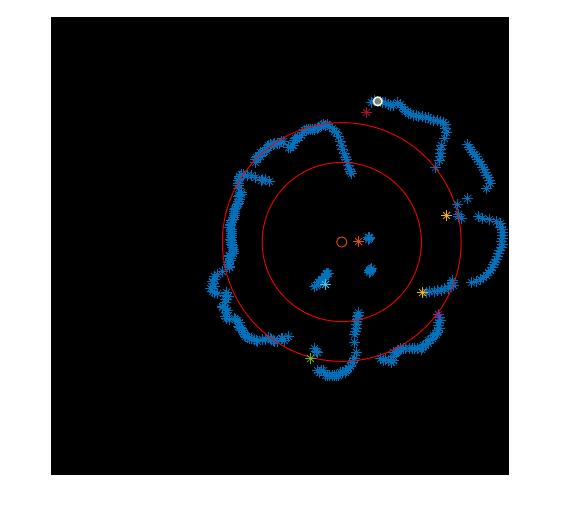

% arreglar lo de arriba
% primero detectar distancias al centro y quitar distancias muy pequeñas y luego juntar los puntos
% despues coger para cada punto la media de distancias de los anteriores y posteriores y si es mucho mas pequeña eliminar

for i = 1:length(angulos)-1
%     if distancias(i)<radius3
%        x_border(i)
%     end

    if sqrt((x_border(i+1)-x_border(i))^2+(y_border(i+1)-y_border(i))^2) > 100
        i
        if abs(distancias(i)-distancia_media)<abs(distancias(i+1)-distancia_media)
                x_border(i+1) = round(centro_x1 + distancias(i) * cos(angulos(i+1)));
                y_border(i+1) = round(centro_y1 + distancias(i) * sin(angulos(i+1)));
               i
               plot(x_border(i+1),y_border(i+1),'*')
        else
                x_border(i) = round(centro_x1 + distancias(i+1) * cos(angulos(i)));
                y_border(i) = round(centro_y1 + distancias(i+1) * sin(angulos(i)));
                plot(x_border(i),y_border(i),'*')
        end
        

    end
end


% figure
% imshow(border)
% hold on
% plot(x_border,y_border,'*') %'-'
% centro_x = round(mean(x_border))
% centro_y = round(mean(y_border))
% plot(centro_x,centro_y,'o')

- todos los sizes no se si es necesario, porque vienen recortados a un tamaño fijo (801*801?)

- chequear que ultimos radios es igual que distancias

function I = imload(file_name)
    I = imread(file_name);
    I = rgb2gray(I);                % gray scale
    I = imresize(I,[2424 3004]);    % same sizes  
    I = im2double(I);               % normalization and double format
end